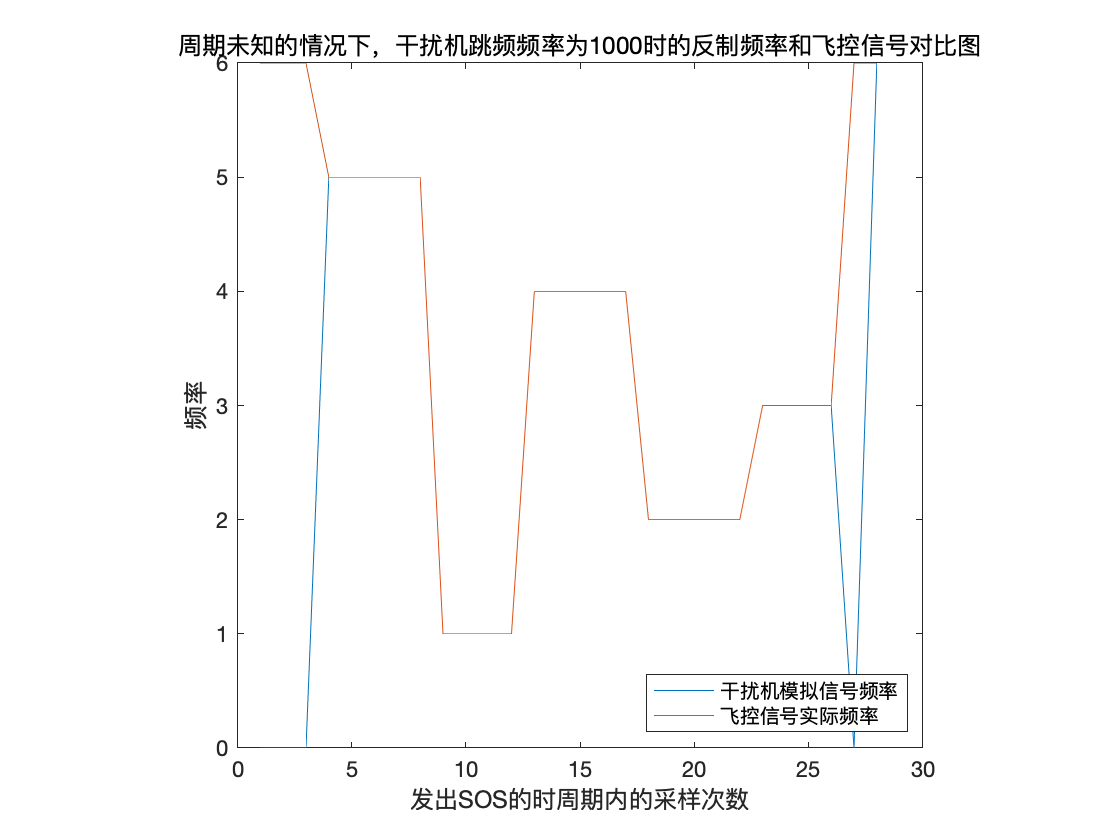

反制成功所花费的时间为:0.234


clear all;
clc;

global H;
global P;
global sig2;
global K;
global pos

%设置基本常量
H=150;%设置无人机飞行高度H,(m)
l0=8;%设置无人机飞行速度l0,(m/s)
P=10;%设置基站发送功率,(W)
sig2=2*1E-5;%设置噪声功率σ2 = 2×10-5,(w)
rho=3.1623;%设置门限ρ1，ρ2
max=100000;%定义搜索次数上限（实际上可能早就早于达到搜索上限之前找到了最佳点）
t=1/217;%定义单次搜索时间
left=[-l0*t,0];
right=[l0*t,0];
up=[0,l0*t];
down=[0,-l0*t];

K=3;%假设共有K个基站
gamma=0.5;%设置折扣因子γ
a0=[100,2700];%设置无人机起始横坐标
b0=[100,3800];%设置无人机起始纵坐标

%设置基础变量
x=zeros(max,2);%无人机第i次搜索之后的坐标,其中第一列为横坐标，第二列为纵坐标

pos=zeros(K,2);%基站的坐标,其中第一列为横坐标，第二列为纵坐标
pos(1,:)=[1350, 1950];
pos(2,:)=[1600, 1790];
pos(3,:)=[1590, 2090];

t22;%运行干扰机

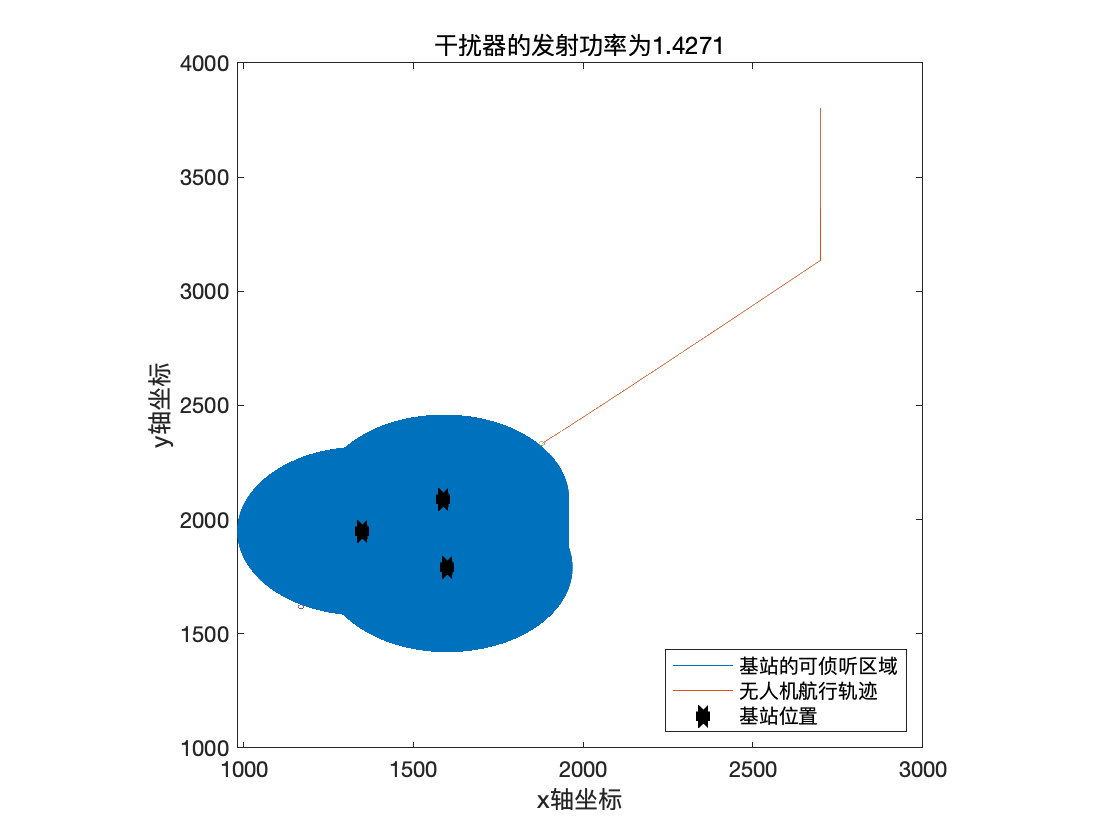


tmax=2000/samp_freq;%设置最长反制时间

r_jammer=tmax*l0/2;%求出最长反制时间对应干扰器有效半径

P_jammer=(H^2+r_jammer^2)*rho*sig2;%通过有效半径来倒推干扰器发射功率

%生成可侦听区域半径
r_safe=sqrt(P/(rho*sig2)-H^2);%以基站为圆心的可侦听的区域的半径
theta = linspace(0,2*pi,10000);%计算可侦听区域
A(:,1) = pos(1,1)+r_safe*cos(theta);
A(:,2) = pos(1,2)+r_safe*sin(theta);
B(:,1) = pos(2,1)+r_safe*cos(theta);
B(:,2) = pos(2,2)+r_safe*sin(theta);
C(:,1) = pos(3,1)+r_safe*cos(theta);
C(:,2) = pos(3,2)+r_safe*sin(theta);
D = union(A,B,'rows');%合并所有基站的可侦听区域
D = union(C,D,'rows');

%计算干扰器位置：

jammer_pos(1,:)=[1168,1619];%计算干扰器1的圆心位置
jammer_pos(2,:)=[1878,2333];%计算干扰器2的圆心位置

%生成干扰器的有效干扰圆域范围
jammer1(:,1)=jammer_pos(1,1)+r_jammer*cos(theta);
jammer1(:,2)=jammer_pos(1,2)+r_jammer*sin(theta);
jammer2(:,1)=jammer_pos(2,1)+r_jammer*cos(theta);
jammer2(:,2)=jammer_pos(2,2)+r_jammer*sin(theta);

R=zeros(max,1);%第i个时刻的和信息速率评价函数


%定义第一次搜索点：

if (rand<0.5)
    init=1;
else
    init=2;
end

ins=left;
best=getR([a0(init),b0(init)]+left);
    
if (best<getR([a0(init),b0(init)]+right))
    ins=right;
    best=getR([a0(init),b0(init)]+right);
end
    
if (best<getR([a0(init),b0(init)]+up))
    ins=up;
    best=getR([a0(init),b0(init)]+up);
end
    
if (best<getR([a0(init),b0(init)]+down))
    ins=down;
    best=getR([a0(init),b0(init)]+down);
end
R(1)=best;
x(1,:)=[a0(init),b0(init)]+ins;

t_1st=0;%初始化第一次进入干扰器有效干扰区域的时间

for i=1:1:max
    
    if(t_1st==0)%判断无人机第一次进入干扰器有效区域的时间点
        if((norm(x(i,:)-jammer_pos(init,:))<=r_jammer))
            t_1st=i;
        end
    end
    
    if (best<getR(x(i,:)+left))
        ins=left;
        best=getR(x(i,:)+left);
    end
    
    if (best<getR(x(i,:)+right))
        ins=right;
        best=getR(x(i,:)+right);
    end
    
    if (best<getR(x(i,:)+up))
        ins=up;
        best=getR(x(i,:)+up);
    end
    
    if (best<getR(x(i,:)+down))
        ins=down;
        best=getR(x(i,:)+down);
    end
    
    if(norm(x((ceil(nack_index/samp_freq)/t+t_1st),:)-jammer_pos(init,:))<=r_jammer)
        index=i;
        break;
    end
    R(i+1)=best;
    x(i+1,:)=x(i,:)+ins;
end

t_1st=t_1st*t;

E=0;
for i=1:1:max
    E=E+power(gamma,i-1)*R(i);
end
%{
fileID = fopen('data_t3.txt','a');
fprintf(fileID,'%d\r\n',index*t);
fclose(fileID);
%}
plot(D(:,1),D(:,2));hold on;%绘制可被侦听区域

plot(x(1:index,1),x(1:index,2));%绘制航迹图
s=scatter(pos(:,1),pos(:,2),"*");%绘制基站位置
plot(jammer1(:,1),jammer1(:,2));%绘制干扰器1的有效干扰范围
plot(jammer2(:,1),jammer2(:,2));%绘制干扰器2的有效干扰范围
s.LineWidth = 5;
s.MarkerEdgeColor = 'black';
axis square;

title(['干扰器的发射功率为',num2str(P_jammer)]);
xlabel('x轴坐标') 
ylabel('y轴坐标') 
legend({'基站的可侦听区域','无人机航行轨迹','基站位置'},'Location','southeast')

function Rtemp=getR(x)%得到和信息速率评价
global H;
global P;
global sig2;
global K;
global pos

d2=zeros(1,K);%无人机距离基站的距离
h=zeros(1,K);%基站与无人机之间的信道功率增益
Rk=zeros(1,K);%无人机的通信基站的信息速率评价函数分量
sum=0;

for j=1:1:K
    d2(j)=H^2+(x(1)-pos(j,1))^2+(x(2)-pos(j,2))^2;
    h(j)=1/d2(j);
    Rk(j)=log2(1+P*h(j)/sig2);
    sum=sum+Rk(j);
end

Rtemp=sum;
end
